Controllo se è rimasta aperta la porta seriale

if(exist('STM32_ser', 'var'))
    delete(STM32_ser);
end

baudrate = 1000000

baudrate = 1000000

porte_libere = serialportlist("available")

porte_libere = 1×2 string array
    "COM4"    "COM5"


STM32_ser = serialport(porte_libere(end), baudrate , Timeout=2);

Connetto alla seriale

buff_size = 400;
measures = 4;

Numero_Misure = 3000;
l =  buff_size*measures

l = 1600

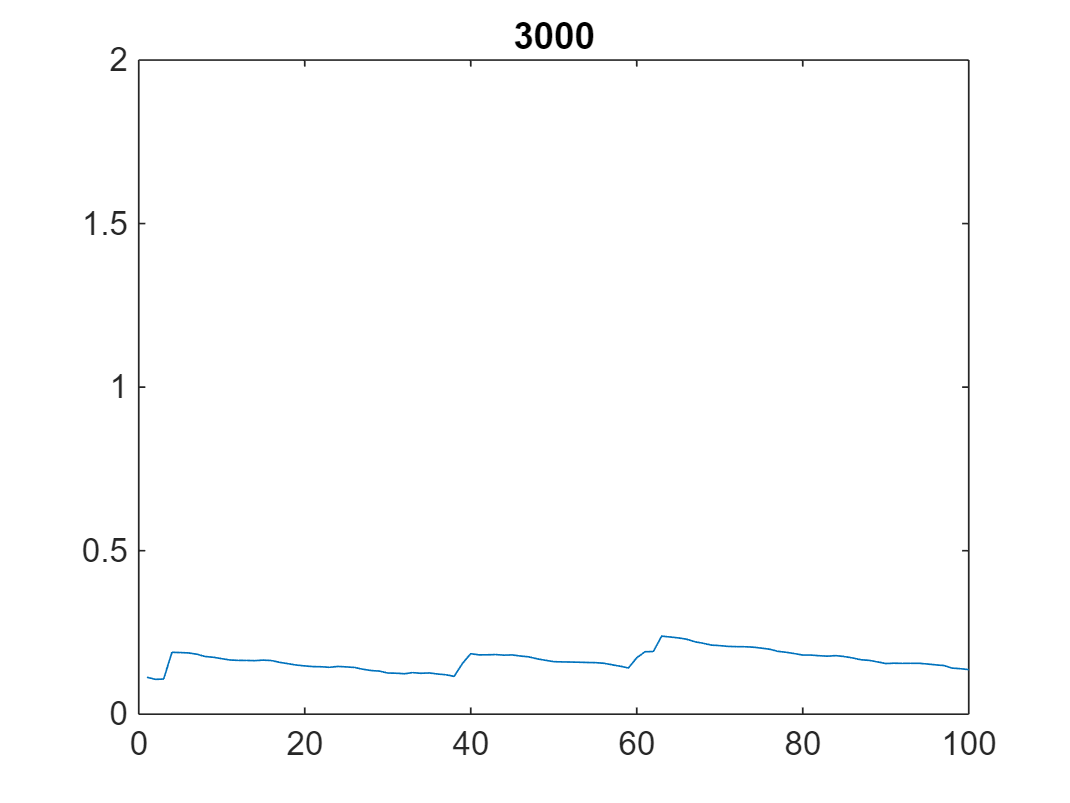

data_buffer = zeros(Numero_Misure,l);
index = 1;

while (index < Numero_Misure+1)
STM32_ser.write('?','char');
% while 1

    STM32_ser.write('?','char');
    data = STM32_ser.read(l,'uint16') ./ 2^16 * 3.3;

    figure(1);
    plot(data(1:100));
    ylim([0,2]);
    title(index);

    data_buffer(index, :) = data;
    index = index + 1;
    drawnow
end

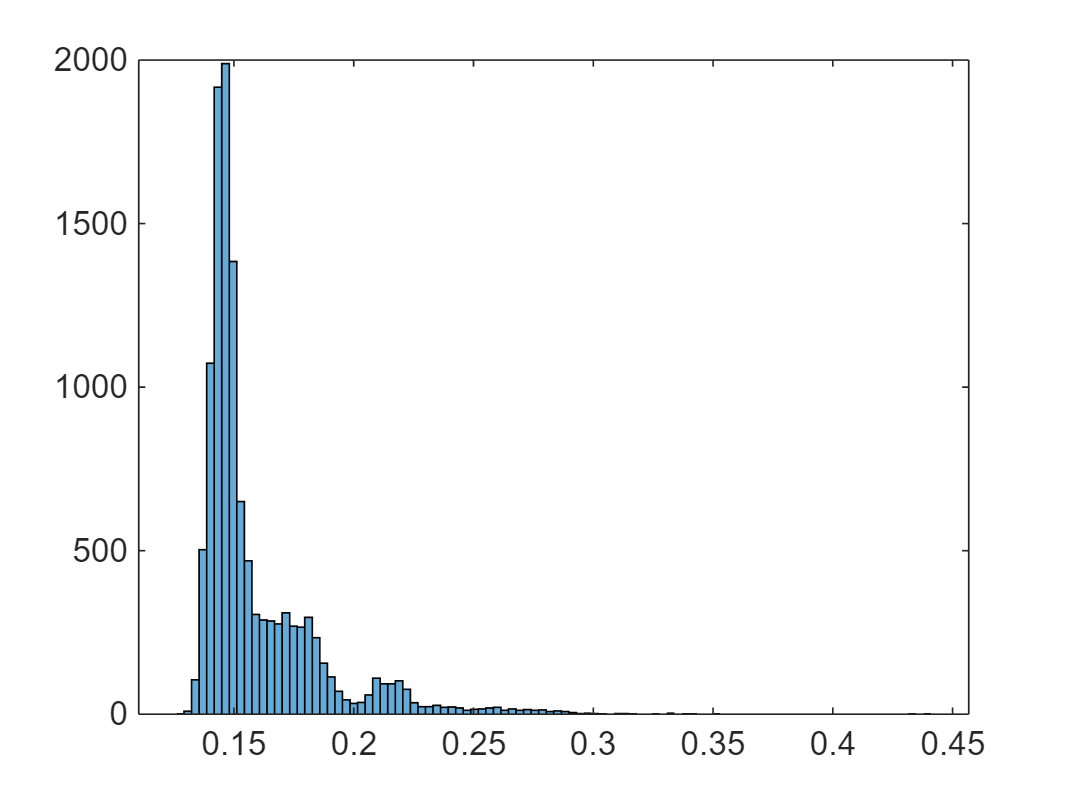

middle_val = zeros(0, Numero_Misure*measures);
for i= 1:Numero_Misure
    for j=1:measures
        indx = (i-1)*(measures) + j;
        middle_val(indx) = data_buffer(i,(j-1)*buff_size + 20);
    end
end
histogram(middle_val,100)

max_val = zeros(0,Numero_Misure*measures);
for i=1:Numero_Misure
    for j=1:measures
        max_val(i*measures + j) = max(data_buffer(i,1:50));
    end
end
bins = int32(1 + log(length(max_val)/log(2)))

bins = int32
11

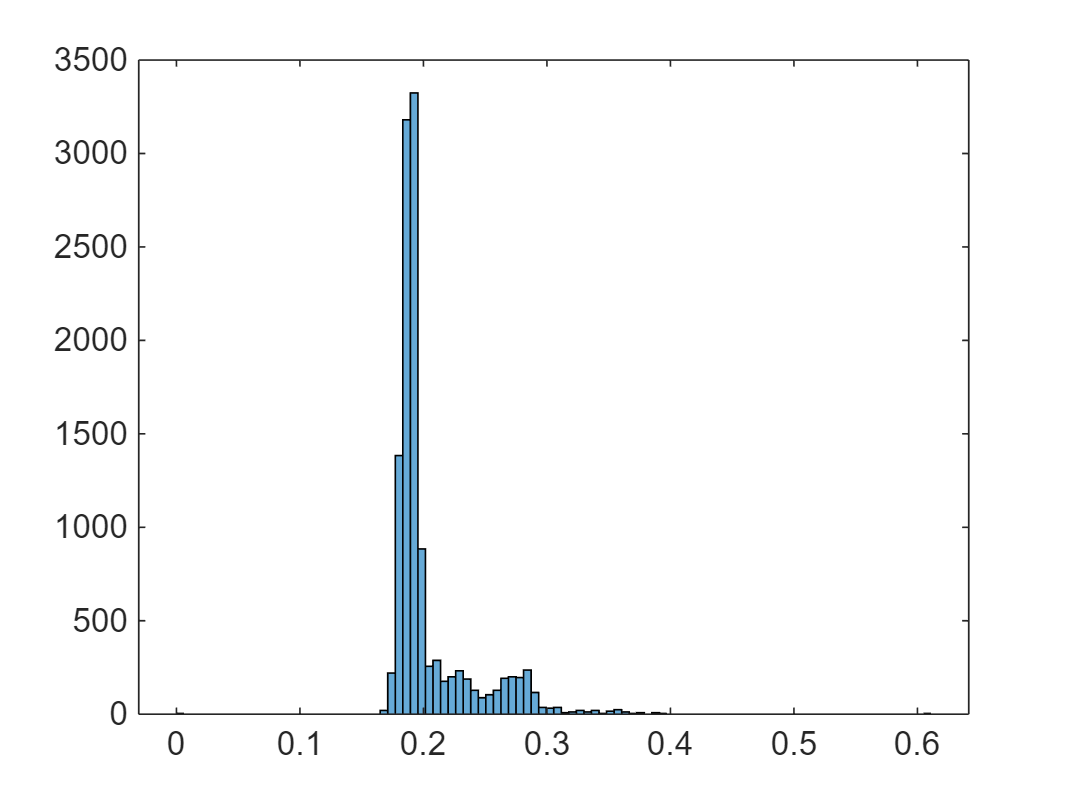

histogram(max_val,100)